# MECH 6323 - Homework 5

**Author:** Jonas Wagner

**Date:** 2022-03-27

close all
clear
% clc

## Problem 1

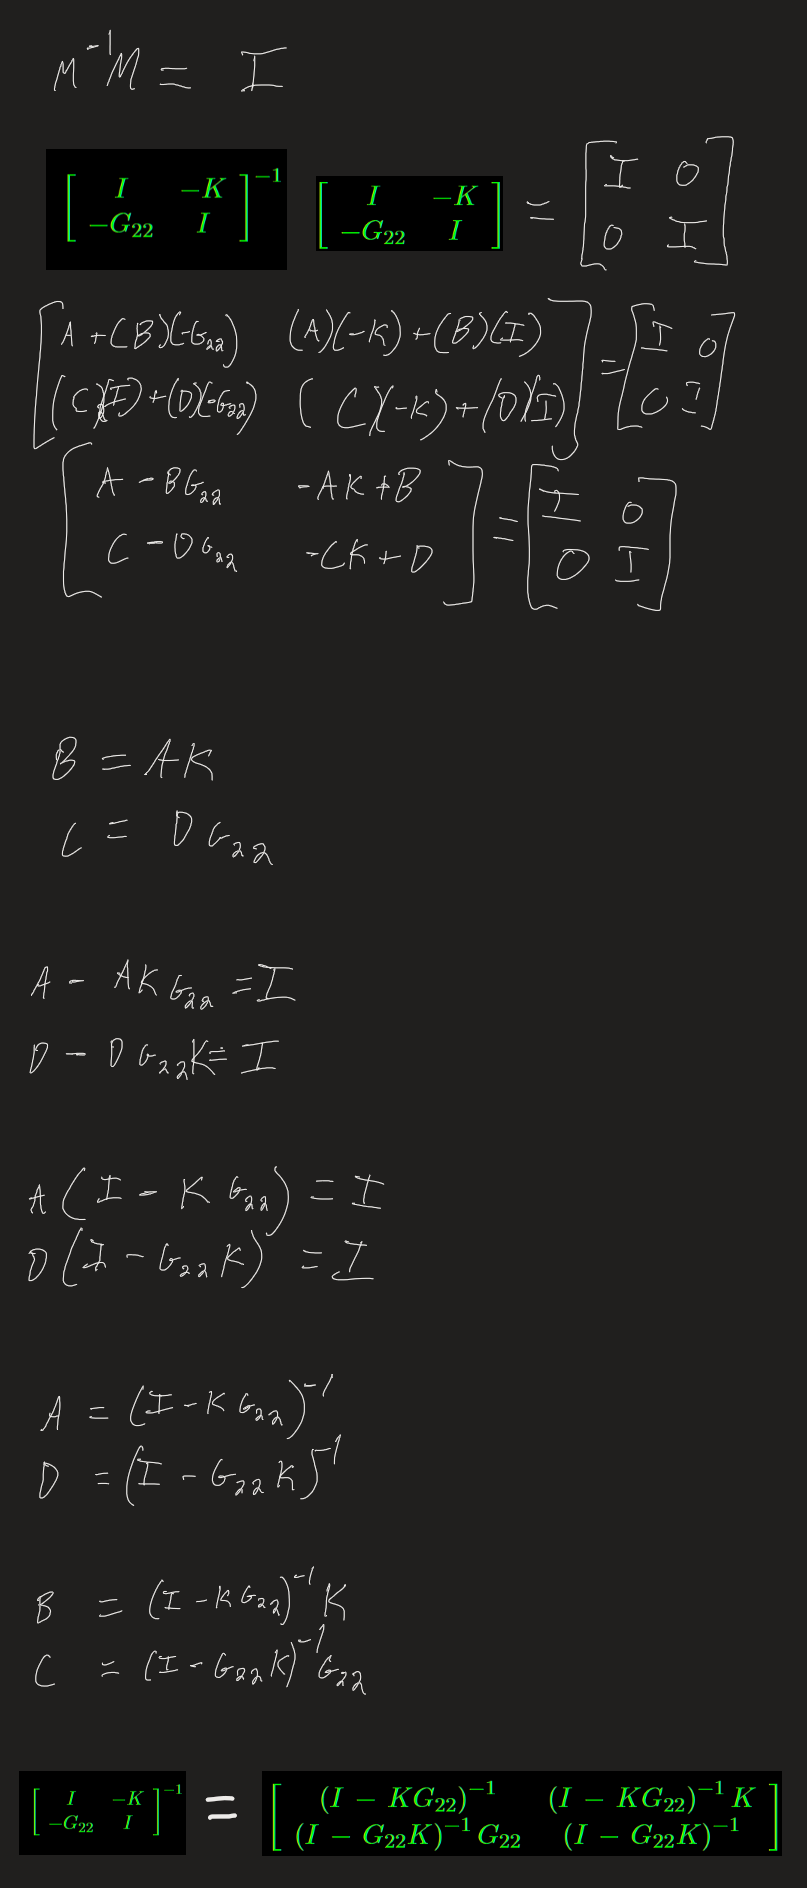

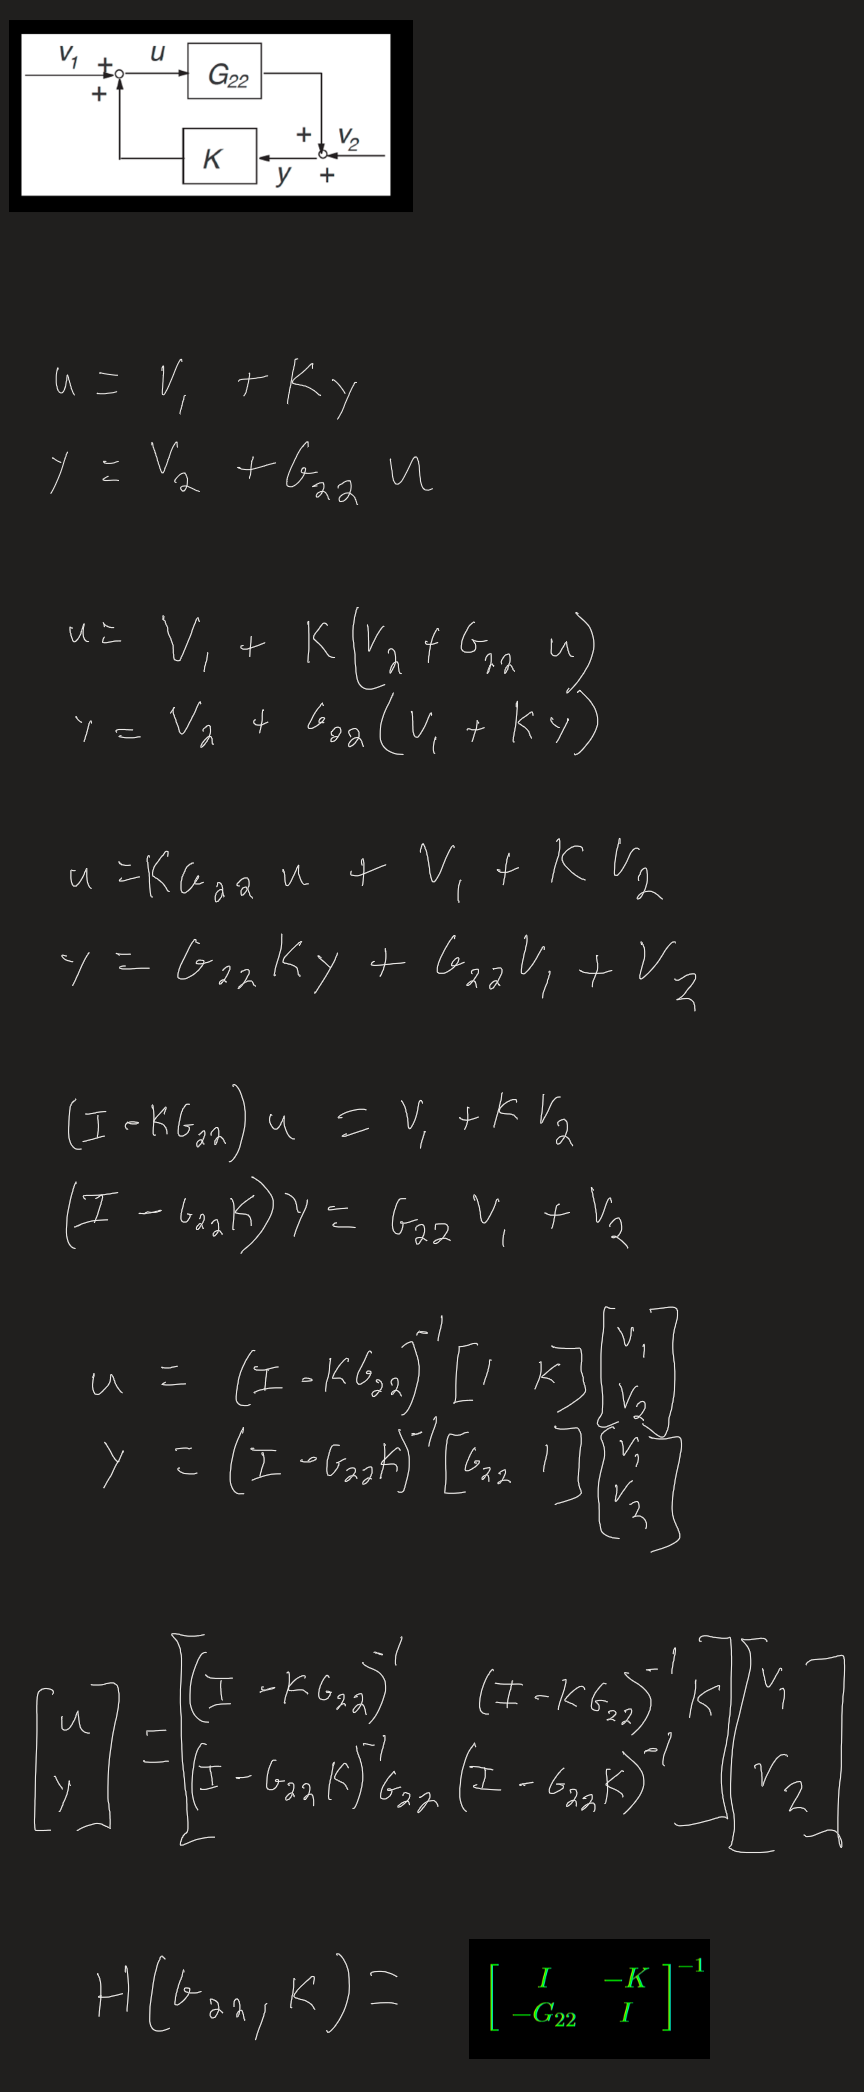

## Problem 2

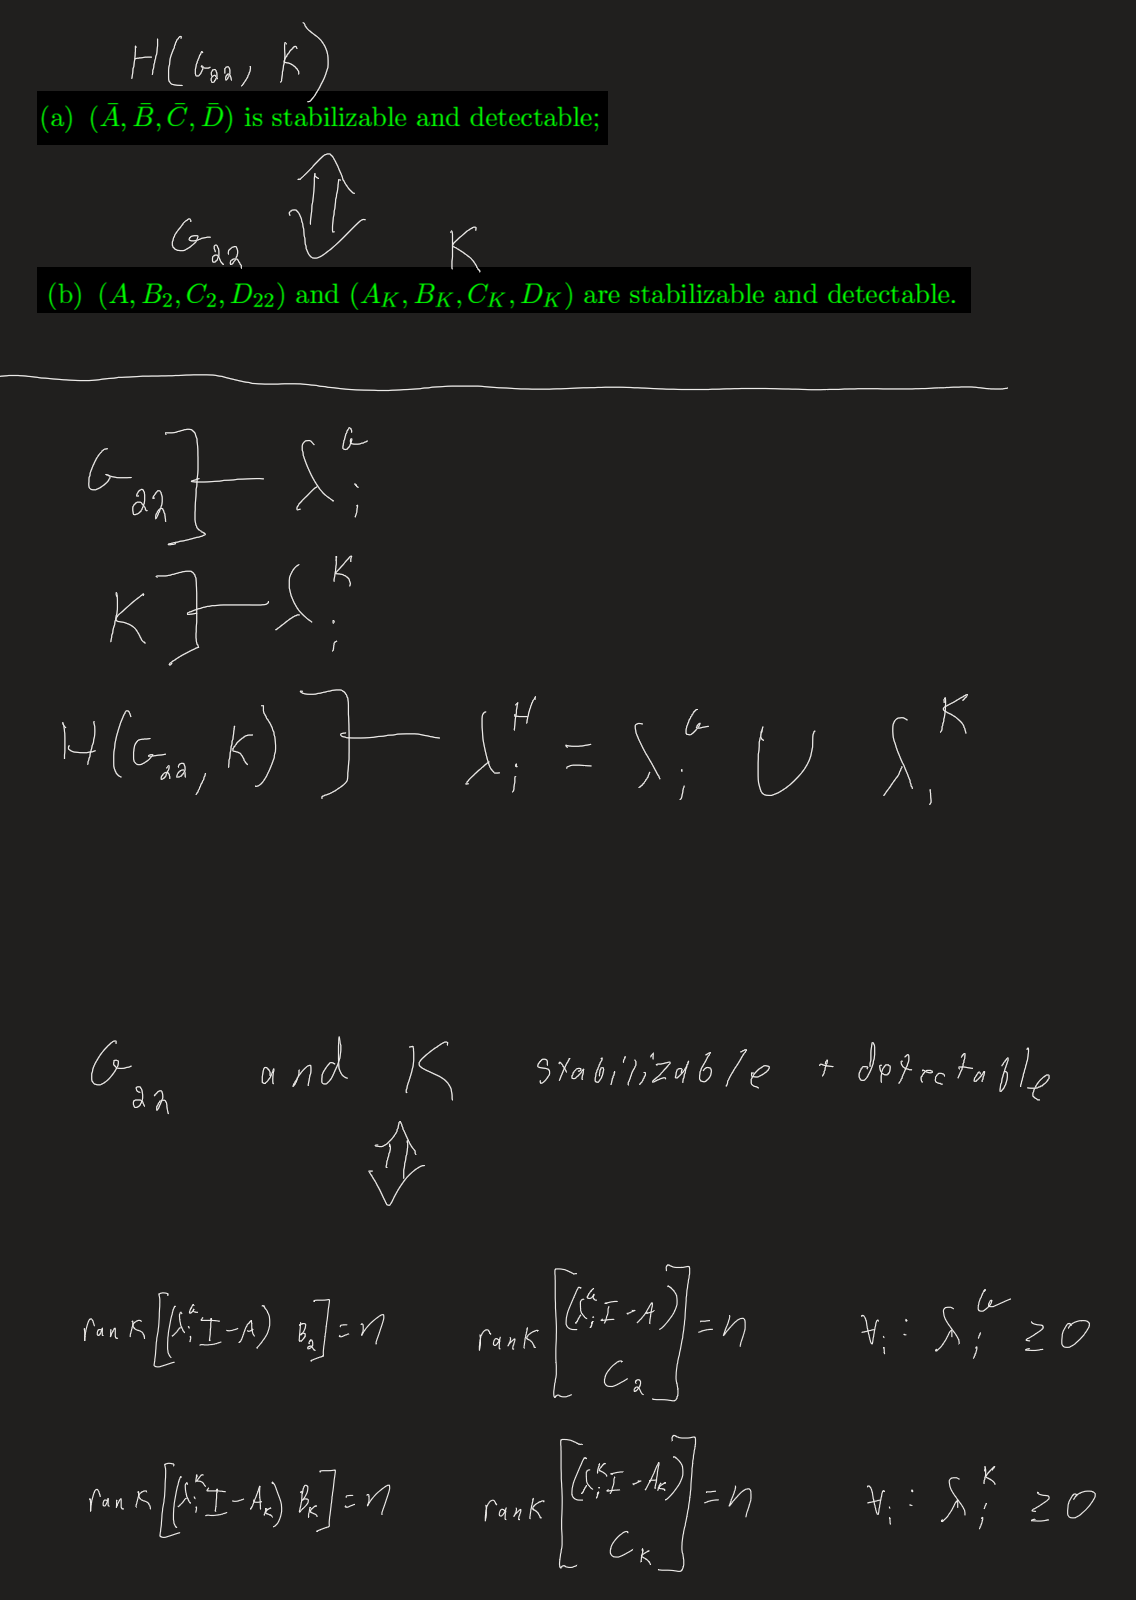

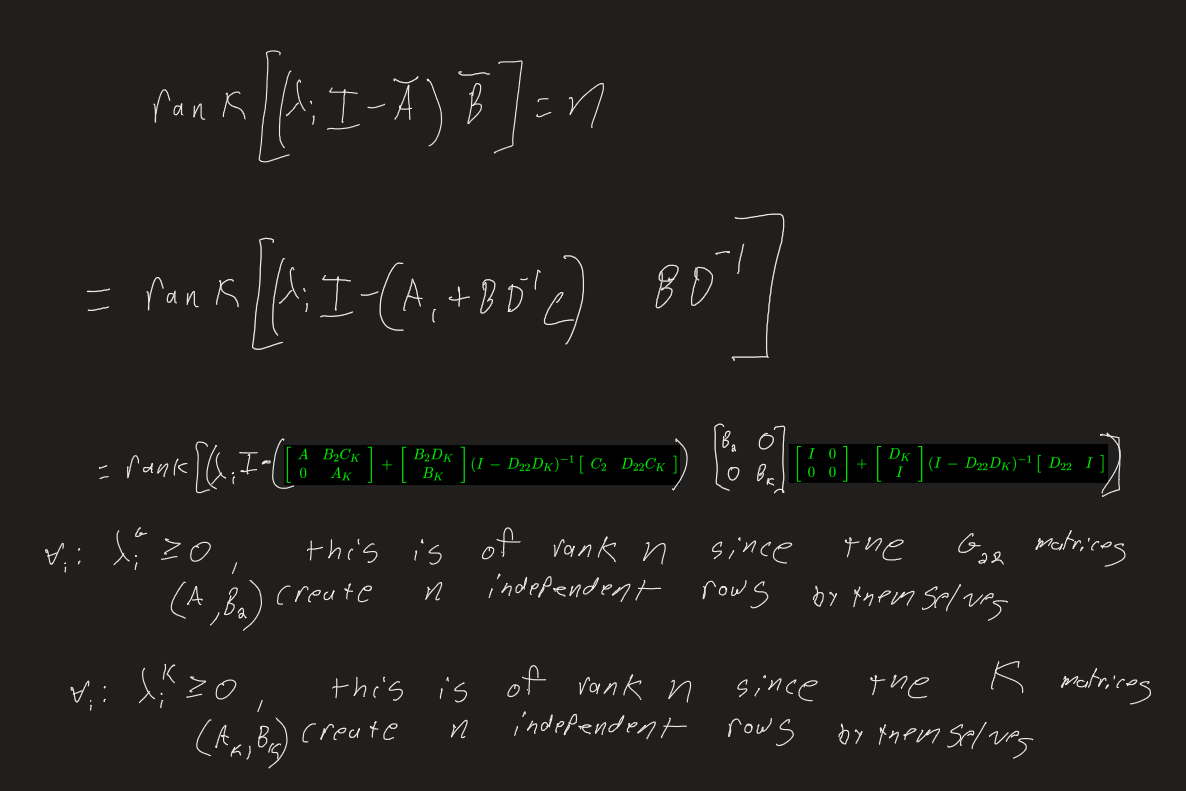

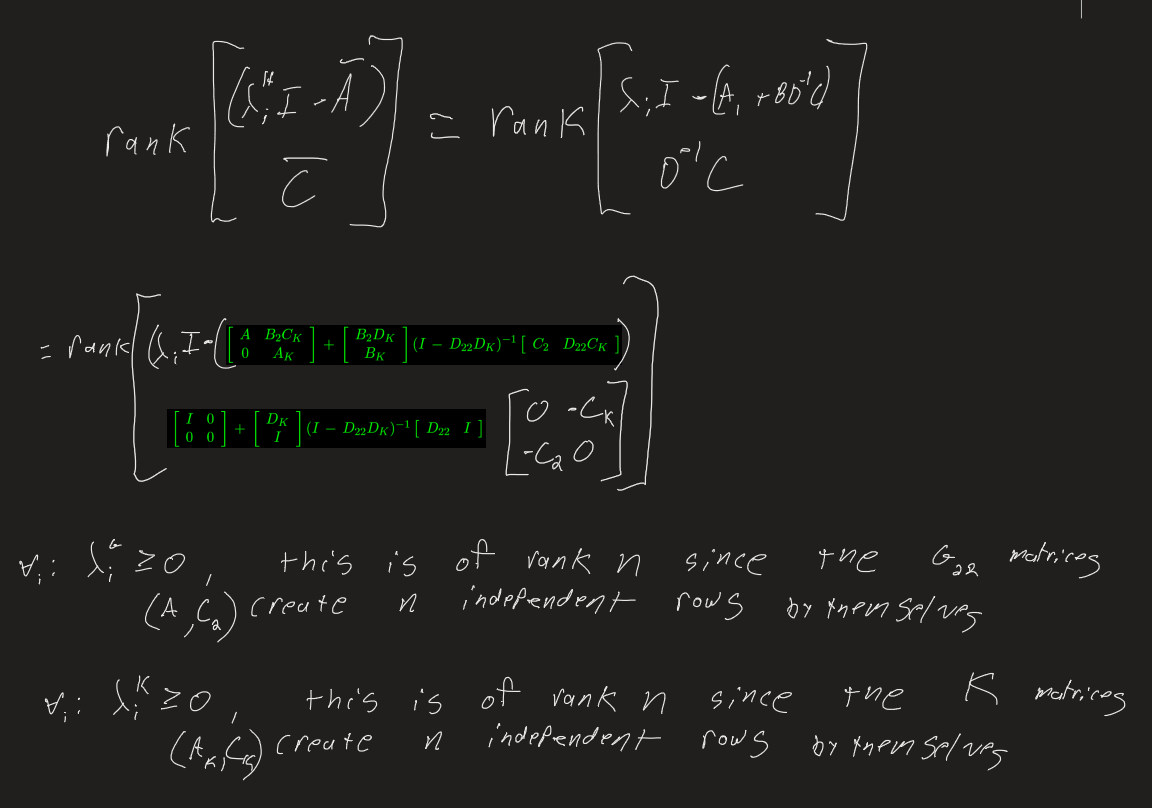

## Problem 3

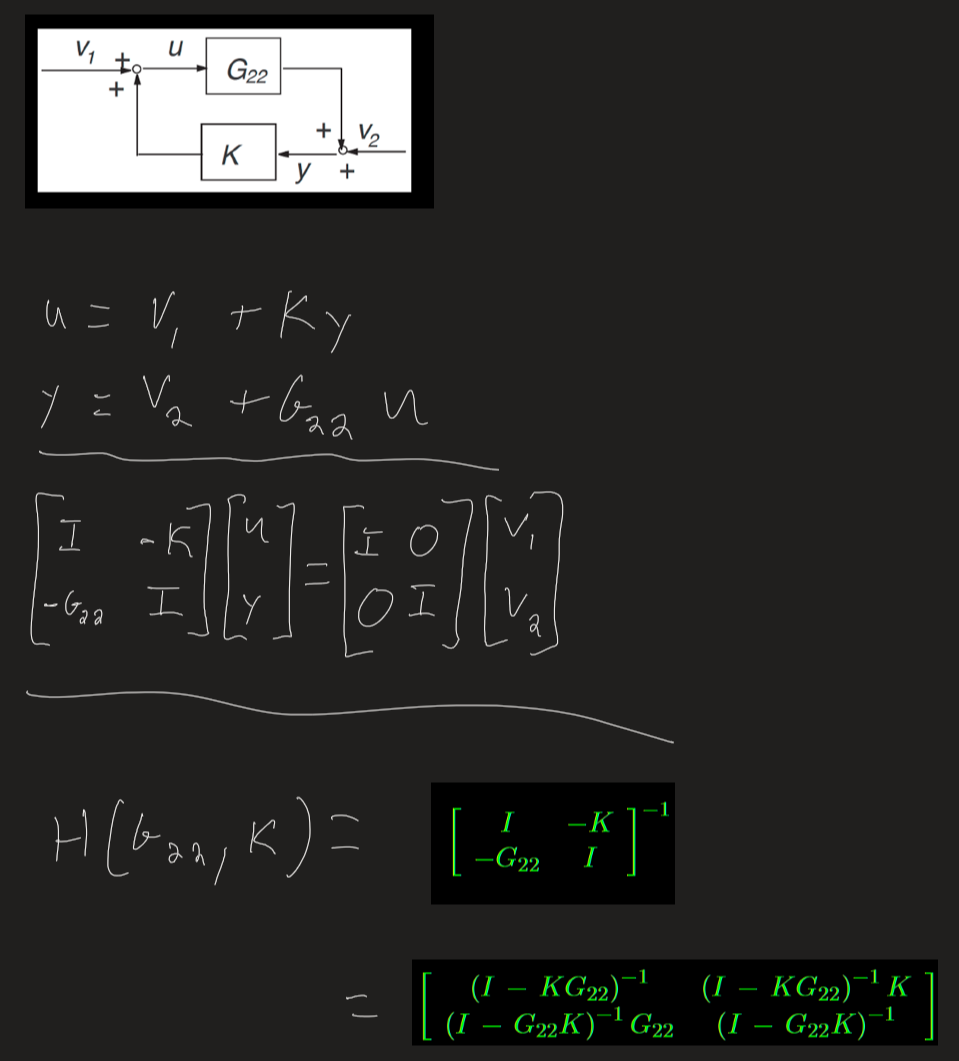

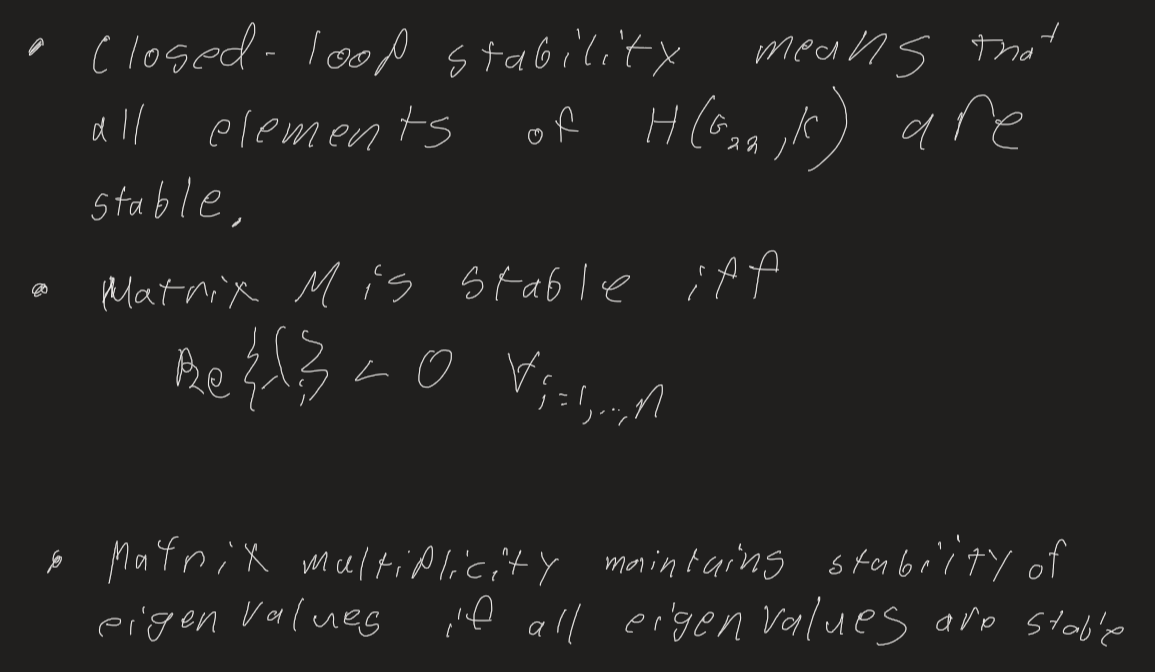

### (i) If $K$ is stable then the closed loop interconnection is stable if and only if $G_{22} (I-KG_{22})^{-1}$ is stable.

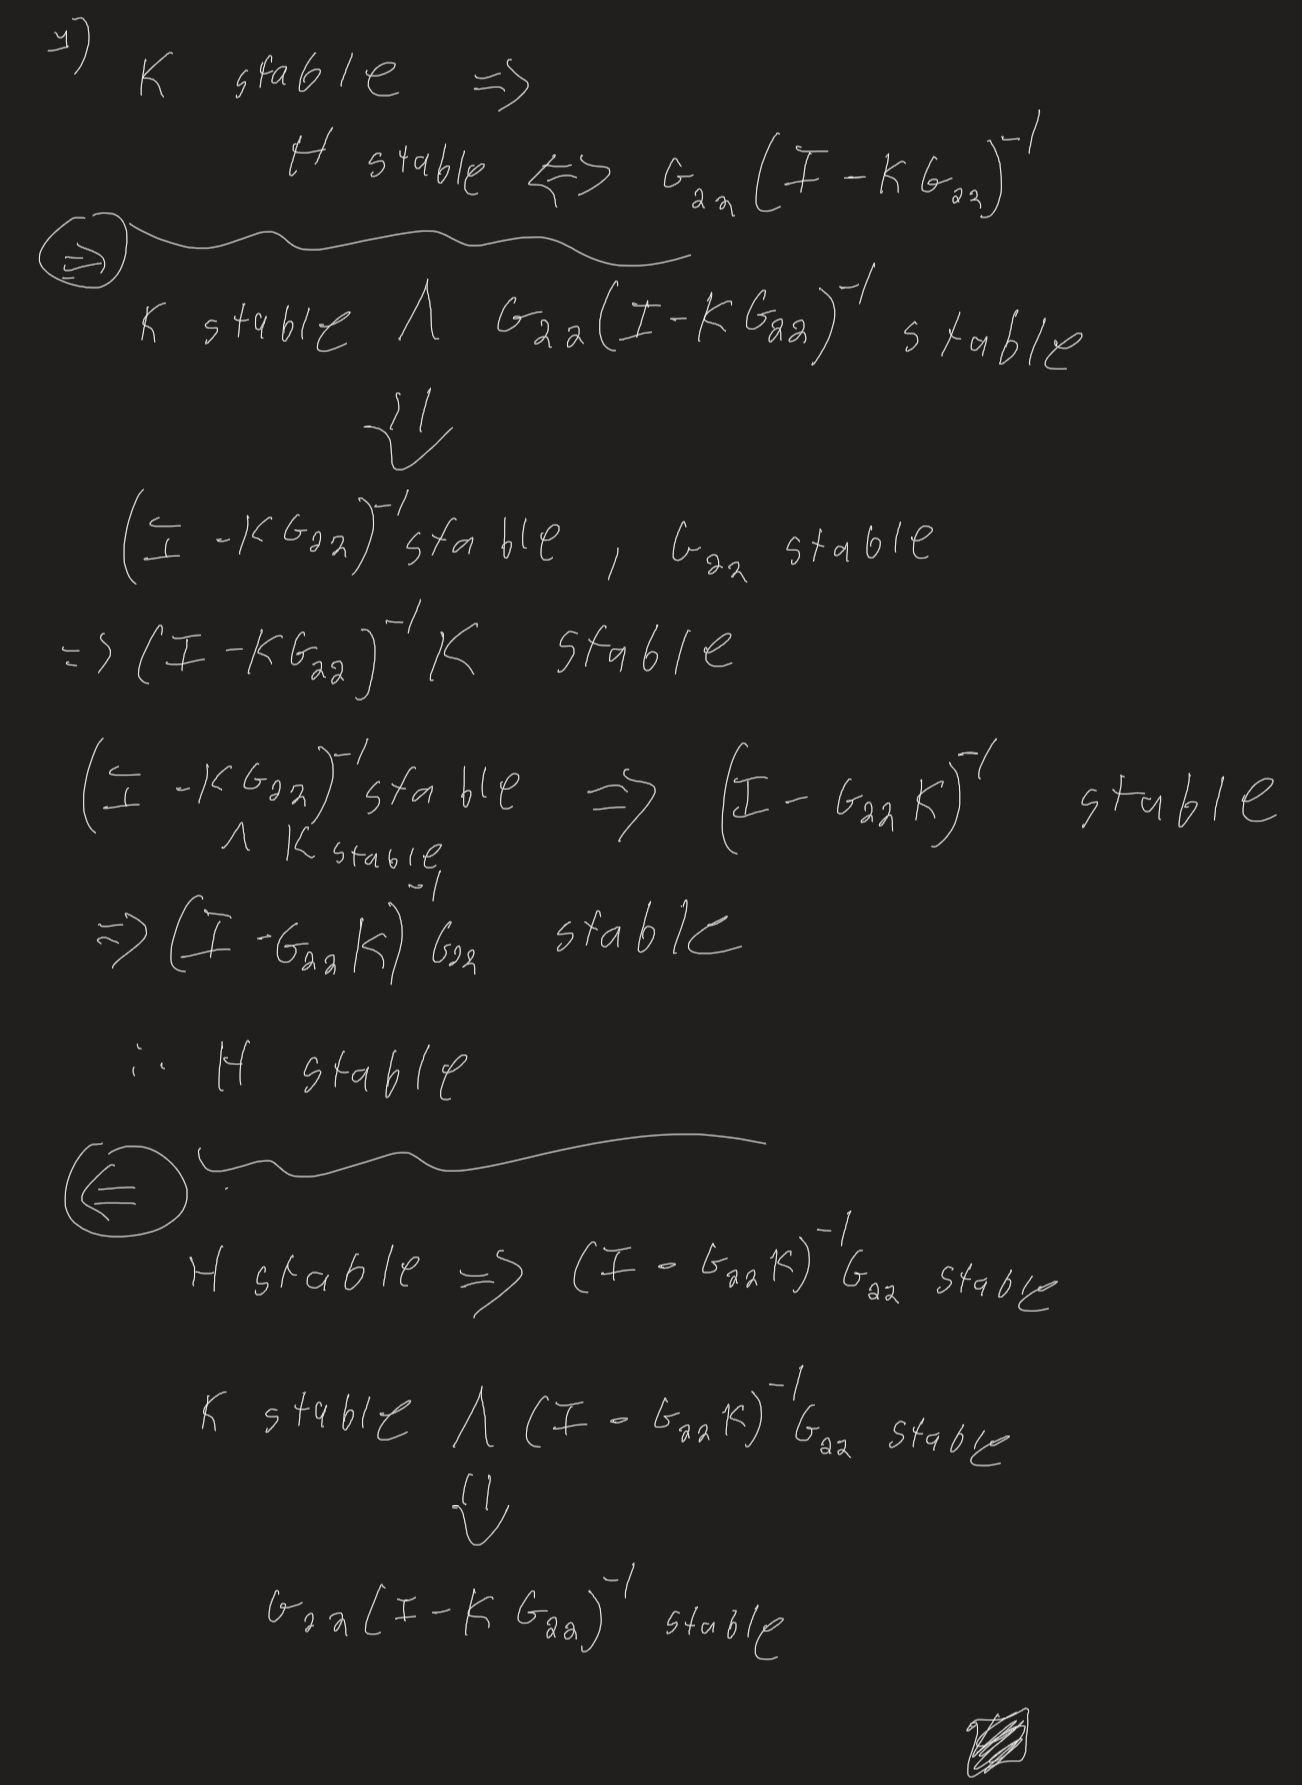

### (ii) If $G_{22}$ is stable then the closed loop interconnection is stable if and only if $K (I-G_{22}K)^{-1}$ is stable.

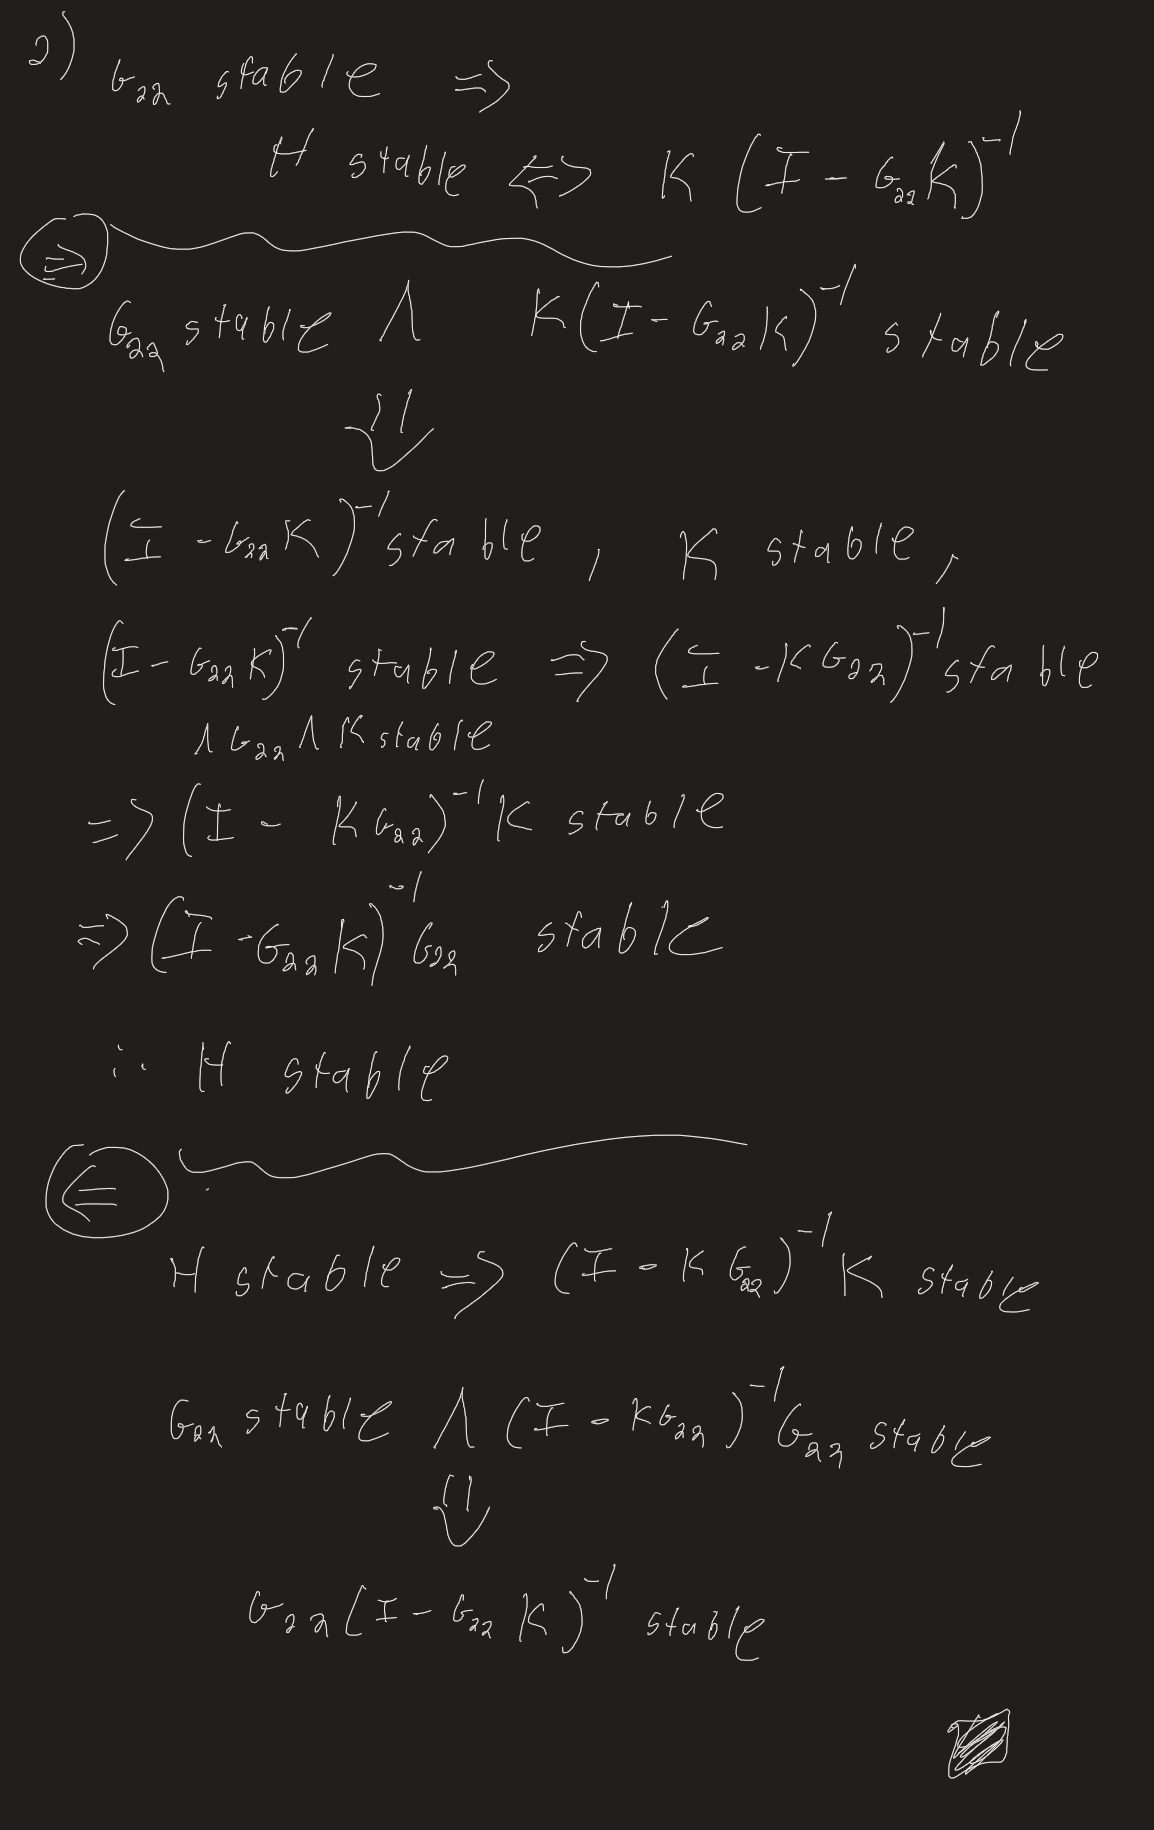

## Problem 4

**Consider the standard negative feedback loop with the nominal plant dynamics **$P(s) = \frac{2}{s+1}$** and controller **$K(s) = 20$**. **

**Assume the "true" dynamics lie within the following multiplicative uncertainty set:**


$$\mathcal{M} := \{\hat{P} = P (1 + W_{u} \Delta) : ||\Delta||_\infty < 1 \text{ and } \Delta \text{ stable}\}$$


**Assume the uncertainty weight is **$W_{u}(s) = \frac{2s + 1}{s + 10}$**.**

P = tf([1], [1 1])

P =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



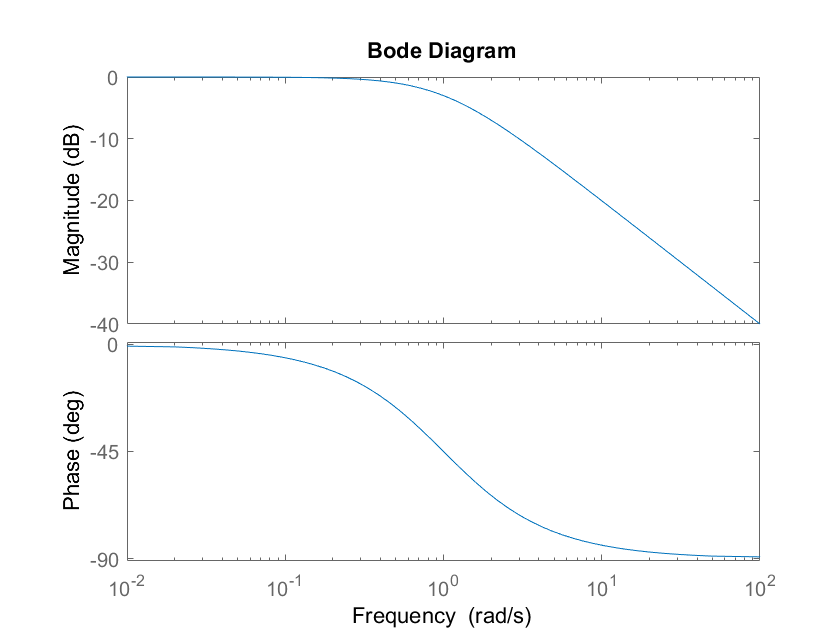

bode(P)

K = tf([20], [1])

K =
 
  20
 
Static gain.



Wu = tf([2 1], [1 10])

Wu =
 
  2 s + 1
  -------
  s + 10
 
Continuous-time transfer function.



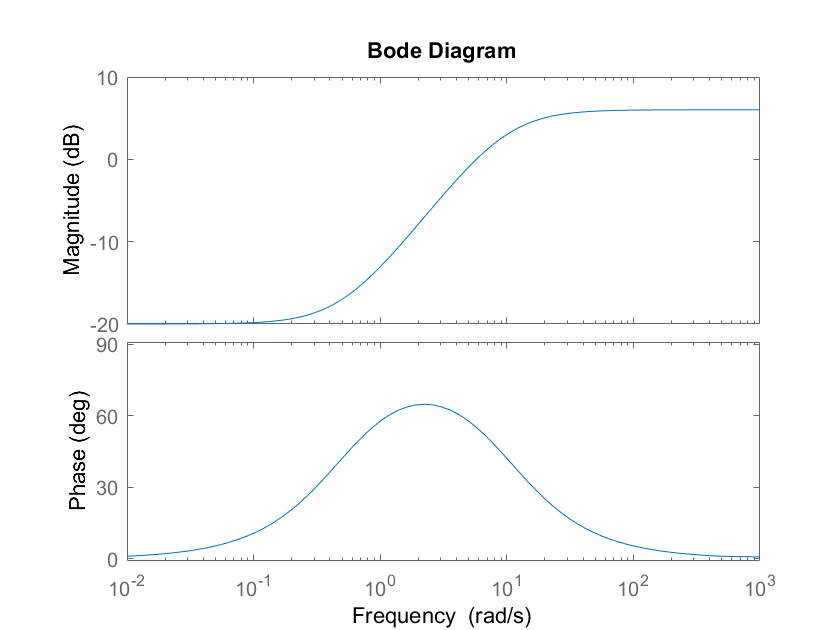

bode(Wu)

### (a) Provide an interpretation for the uncertainty described by the weight $W_u$.

A frequency dependent uncertainty that describes the modeling inacuracies of the system for frequencies increasing from 

### (b) 

#### Is the nominal system stable?

closed_nom_stable = isstable(1+K*P)

closed_nom_stable = logical
   1


Yes

#### What are the gain and phase margins of the nominal loop $L=PK$?

L = P * K

L =
 
   20
  -----
  s + 1
 
Continuous-time transfer function.



[Gm_L, Pm_L, Wcg_L, Wcp_L] = margin(L);
disp(['Gain Marigin: ', num2str(Gm_L)])

Gain Marigin: Inf


disp(['Phas Marigin: ', num2str(Pm_L)])

Phas Marigin: 92.8663


### (c) 

**The robust stability condition for this type of multiplicative uncertainty is stated as: **

$K$ stabilizes all $\hat{P} \in \mathcal{M}$ if and only if $||W_u T||_\infty \leq 1$.

T = feedback(L,1)

T =
 
    20
  ------
  s + 21
 
Continuous-time transfer function.



WuT = Wu * T

WuT =
 
     40 s + 20
  ----------------
  s^2 + 31 s + 210
 
Continuous-time transfer function.



WuT_norm = norm(WuT,'inf')

WuT_norm = 1.2911

#### Does  robustly stabilize all models in  based on this condition?

No. Since $||W_u T||_\infty = 1.2911 > 1$, the robust stability condition is not satisfied.

### (d) 

#### Construct the uncertain model Phat

Delta = ultidyn('Delta', [1 1]);
Phat = P * (1 + Wu * Delta);

#### Generate a Bode magnitude plot with 10 samples drawn from the uncertainty set and draw the nominal response $P$ on

#### the same plot.

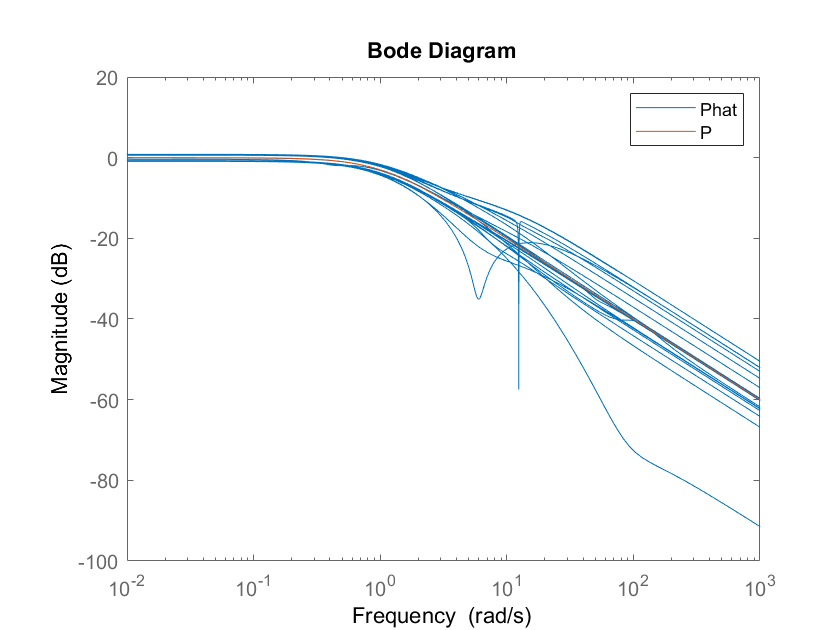

pblm4_d = figure();
hold on
bodemag(Phat)
bodemag(P)
legend

### (e)

#### Perform the robustness test with robstab

Lhat = Phat * K;
That = feedback(Lhat,1);
opts = robOptions('Display','on','Sensitivity','on');
[stabmarg, destabunc, report] = robstab(That, opts);

Computing peak...  Percent completed: 100/100
System is not robustly stable for the modeled uncertainty.
 -- It can tolerate up to 77.3% of the modeled uncertainty.
 -- There is a destabilizing perturbation amounting to 77.5% of the modeled uncertainty.
 -- This perturbation causes an instability at the frequency 14.5 rad/seconds.
 -- Sensitivity with respect to each uncertain element is:                
      100% for Delta. Increasing Delta by 25% decreases the margin by 25%.


#### Does the result obtained with robstab agree with your conclusions in part (c)?

Yes. The system is not robustly stable becouse a destabilizing pertubation exists with 77.5% model uncertainty at frequency 14.5 rad/s.